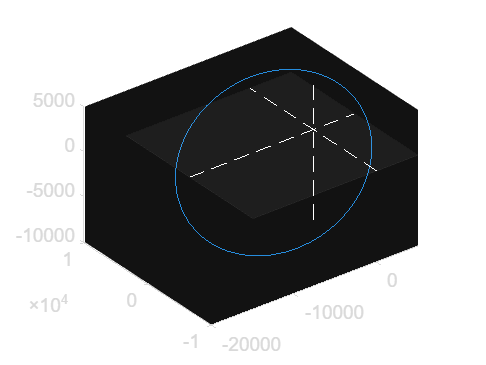

% STATIC ORBIT
[a, e, i, w, O] = deal(10000, 0.5, 45*pi/180, pi/4, -pi/4);
% theta = pi/2;
ang_res = 0.1;
theta = 0:ang_res:2*pi+ang_res;
[p, f, g, h, k, L] = class2mod(a, e, i, w, O, theta);
[x, y, z] = mod2XCI(p, f, g, h, k, L);

% mod_param = [p, f, g, h, k, L];

figure(1)
clf
plot3(x, y, z, '-')
% xlim([-a*2 a*2])
% ylim([-a*2 a*2])
% zlim([-a*2 a*2])
axisPlot(1,'w')
run planeXY.m
daspect([1 1 1])

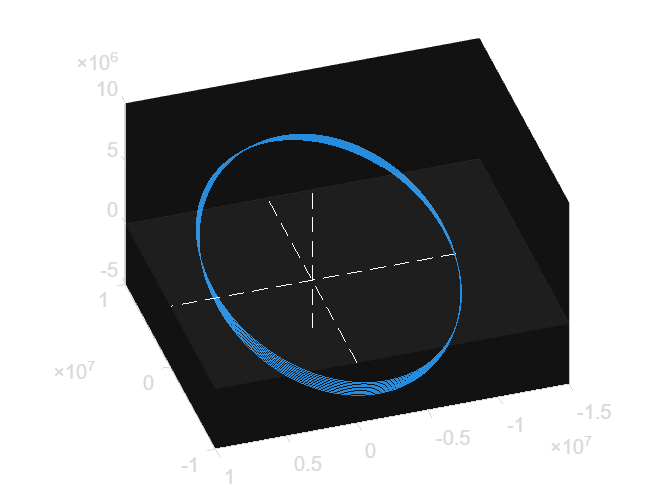

[a, e, i, w, O, theta] = deal(10000e3, 0.02, 45*pi/180, pi/4, -pi/4, 0);
[p, f, g, h, k, L] = class2mod(a, e, i, w, O, theta);
mod_param0 = [p, f, g, h, k, L];
mu = 3.986004418e14; % m3 s-2
sys = @(t,x)orbital_system(t, x, mu, [0 0 0]');
tf = 1e5;

opts = odeset(MaxStep=0.5);
[t, mod_param] = ode45(sys,[0 tf], mod_param0, opts);
p = mod_param(:,1);
f = mod_param(:,2);
g = mod_param(:,3);
h = mod_param(:,4);
k = mod_param(:,5);
L = mod_param(:,6);
[x, y, z] = mod2XCI(p, f, g, h, k, L);

figure(2)
clf
plot3(x, y, z, '-')
% xlim([-a*2 a*2])
% ylim([-a*2 a*2])
% zlim([-a*2 a*2])
axisPlot(2,'w')
run planeXY.m
daspect([1 1 1])

t0 = datetime(2023,11,13,9,0,0)

t0 = datetime
   13-Nov-2023 09:00:00


tfin = t0 + seconds(tf);
sample_time = 60;
positionsTT = timetable([x y z], RowTimes=seconds(t));
sc = satelliteScenario(t0,tfin,sample_time);

sat = satellite(sc,positionsTT,Name = "Spacecraft");
v = satelliteScenarioViewer(sc,CameraReferenceFrame = "Inertial");